Load equations and symbols from file

load symbols.mat
load CoreEquations.mat
load DesignParameters.mat
%load DesignParametersExtraMass.mat

Calculate torque requirements for different movements

%Stage 1: Lifting against step from ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol1 = mysolver(Eqns);
sol1.T_z/2
%Draw positions
drawfigure(sol1);

syms F_react5g F_react5w [3,1]
eq2= [
    M_react53==sol1.M_react53;
    F_react51 == sol1.F_react51;
    F_react52 == sol1.F_react52;
    % C_friction5 == sol1.C_friction5;
    rw == sol1.rw
    C_friction5 == F_react5g1/F_react5g2;
    C_friction5 == -F_react5w2/F_react5w1;
    F_react51 == F_react5g1 + F_react5w1;
    F_react52 == F_react5g2 + F_react5w2;
    M_react53 == -rw*(F_react5g1+F_react5w2)
    C_friction5 > 0;
]
[solvy, unsolved] = mysolver(eq2, 0)
solvx.C_friction5
solvx.F_react5g1
solvx.F_react5g2
solvx.F_react5w1
solvx.F_react5w2
sol1.C_friction5

% sol = sol1
% f=figure('visible','on');
% hold on;
% %wheels
% circle(sol.s61, sol.s62, sol.rw);
% line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
% 
% circle(sol.s51, sol.s52, sol.rw);
% line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
% 
% %frame
% line([sol.s51,sol.s61],[sol.s52,sol.s62])
% 
% %Tail
% line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
% figure
% axis equal;
% axis on;
% ax = gca;
% ax.XAxisLocation = 'origin';
% ax.YAxisLocation = 'origin';
% xlim([-0.7,0.7])
% %ylim([-0.1, 0.5])
% %step
% corner(:,1) = [sol.step_start1-10; sol.step_start2];
% for i= 1:5
%     corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
%     corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
% end
% line(corner(1,:), corner(2,:))
% hold off;

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    s62 == rw; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

[sol2, unsolved] = mysolver(Eqns, 1);
sol2.T_z/2
drawfigure(sol2);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z/2
drawfigure(sol3);

%Stage 1: Lifting against step from first step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    pi/2 < t73; t73 < pi;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z/2
drawfigure(sol3);

%Stage 6: Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    s62 == rw+step_height; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol4 = mysolver(Eqns);
sol4.T_z/2
drawfigure(sol4);

%Stage 6:Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol5 = mysolver(Eqns);
sol5.T_z/2
drawfigure(sol5);

%Stage 4:Lifting against step from second step with tail on first step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
sol6 = mysolver(Eqns);
sol6.T_z/2
drawfigure(sol6);

Test stall torques across movements each movement


%Test stall torques across stage 1 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    t23 == 0;
    ];
solutions1 = solveParallel(Eqns, t13, linspace(0, pi/2, 100))

for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    Crange(i) = solutions1(i).C_friction5;
    thetarange(i) =solutions1(i).t13*180/pi;
end

plot(thetarange, Trange)
hold on
plot(thetarange, Crange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off

%Test stall torques across stage 2 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants(3:4);
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set vertical accelleration of top wheel to zero to solve for movement
    a62 == 0;
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    t23 == 0;
    ];
solutions2 = solveParallel(Eqns, t13, linspace(pi/2, pi-0.74188086214972967258453186960347, 100))

for i = 1:length(solutions2)
    Trange(i) = solutions2(i).T_z;
    Crange = solutions2(i).C_friction5;
    thetarange(i) =solutions2(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([90,180-42.5])
ylim([-1.2, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 3 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions3 = solveParallel(Eqns, t13, linspace(-0.74188086214972967258453186960347, 0, 100));

for i = 1:length(solutions3)
    Trange(i) = solutions3(i).T_z;
    thetarange(i) =solutions3(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2

%Test stall torques across stage 1 movement on second step
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw + step_width; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    t23 == 0;
    ];
solutions12 = solveParallel(Eqns, t13, linspace(0, pi/2, 100))

for i = 1:length(solutions12)
    Trange(i) = solutions12(i).T_z;
    thetarange(i) =solutions12(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 2 movement on second step
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants(3:4);
    %Set position of front wheel
    s51 == -rw + step_width; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    t23 == 0;
    ];
solutions22 = solveParallel(Eqns, t13, linspace(pi/2, pi-0.74188086214972967258453186960347, 100))

for i = 1:length(solutions22)
    Trange(i) = solutions22(i).T_z;
    thetarange(i) =solutions22(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 3 movement on second step
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width*2-rw-0.075; s52 == rw+step_height*2;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions32 = solveParallel(Eqns, t13, linspace(-0.74188086214972967258453186960347, 0, 100));

for i = 1:length(solutions32)
    Trange(i) = solutions32(i).T_z;
    thetarange(i) =solutions32(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2

%Test stall torques across stage 4 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions4 = solveParallel(Eqns, t13, linspace(0, pi/2, 100));

for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    thetarange(i) =solutions4(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")


%Test stall torques across stage 5 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants(3:4);
    %Set position of front wheel
    s51 == 2*step_width-rw; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions5 = solveParallel(Eqns, t13, linspace(pi/2, pi-0.74188086214972967258453186960347, 100))

for i = 1:length(solutions5)
    Trange(i) = solutions5(i).T_z;
    thetarange(i) =solutions5(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 6 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 3*step_width-rw-0.075; s52 == rw+3*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
solutions6 = solveParallel(Eqns, t13, linspace(-0.74188086214972967258453186960347, 0, 100));

for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    thetarange(i) =solutions6(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2

save solutions.mat solutions1 solutions2 solutions3 solutions12 solutions22 solutions32 solutions4 solutions5 solutions6
% load solutions.mat

Plot torques across complete movement

%First movement 1
for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    Crange(i) = solutions1(i).C_friction5;
    thetarange(i) =solutions1(i).t13*180/pi;
end
PlotTorque = Trange;
PlotFriction = Crange;
PlotTheta = thetarange;

%Movement 2
for i = 1:length(solutions2)
    Trange(i) = solutions2(i).T_z;
    Crange(i) = solutions2(i).C_friction5;
    thetarange(i) =solutions2(i).t13*180/pi;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 3
for i = 1:length(solutions3)
    Trange(i) = solutions3(i).T_z;
    Crange(i) = solutions3(i).C_friction5;
    thetarange(i) =solutions3(i).t13*180/pi+180;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 1 on step
for i = 1:length(solutions12)
    Trange(i) = solutions12(i).T_z;
    Crange(i) = solutions12(i).C_friction5;
    thetarange(i) =solutions12(i).t13*180/pi+180;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 2 on step
for i = 1:length(solutions22)
    Trange(i) = solutions22(i).T_z;
    Crange(i) = solutions22(i).C_friction5;
    thetarange(i) =solutions22(i).t13*180/pi+180;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 3 on step
for i = 1:length(solutions32)
    Trange(i) = solutions32(i).T_z;
    Crange(i) = solutions32(i).C_friction5;
    thetarange(i) =solutions32(i).t13*180/pi+360;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 4
for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    Crange(i) = solutions4(i).C_friction5;
    thetarange(i) =solutions4(i).t13*180/pi+360;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 5
for i = 1:length(solutions5)
    Trange(i) = solutions5(i).T_z;
    Crange(i) = solutions5(i).C_friction5;
    thetarange(i) =solutions5(i).t13*180/pi+360;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 6
for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    Crange(i) = solutions6(i).C_friction5;
    thetarange(i) =solutions6(i).t13*180/pi+540;
end
PlotTorque = [PlotTorque, Trange];
PlotFriction = [PlotFriction, Crange];
PlotTheta = [PlotTheta, thetarange];

%Movement 4
for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    Crange(i) = solutions4(i).C_friction5;
    thetarange(i) =solutions4(i).t13*180/pi+540;
end
PlotTorque = [PlotTorque, Trange, 0];
PlotFriction = [PlotFriction, Crange, 0];
PlotTheta = [PlotTheta, thetarange, 630];

for i= 1:length(PlotTheta)
    if PlotFriction(i) < 0
        PlotFriction(i) = 0;
    end
    if PlotTorque(i) < 0
        PlotTorque(i) = 0;
    end
end

f= figure;
plot(PlotTheta, PlotTorque)
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
f.CurrentAxes.XTick=0:90:630;
xlim([0,630])
xline(90:90:630,"--")
xline([180:180:540]-0.74188086214972967258453186960347*180/pi,"--")
hold off

f= figure;
plot(PlotTheta, PlotFriction)
ylabel("Coefficient of friction required to prevent slipping")
xlabel("LIM Angle [°]")
f.CurrentAxes.XTick=0:90:630;
xlim([0,630])
xline(90:90:630,"--")
xline([180:180:540]-0.74188086214972967258453186960347*180/pi,"--")
hold off

drawfigure(solutions1(1))

testvar = vpa(PlotTheta)

%Test stall torques with varying gear ratios
%remove certain parameters
reducedParameters = setdiff(DesignParameters, assignment_gears)

$$reducedParameters = \left(\begin{array}{c} I_{3}=\frac{7895689082865203}{590295810358705651712}\\ m_{4}=m_{3}\\ m_{6}=m_{5}\\ \mathrm{ratio7Weight}=\frac{L_{\mathrm{body},\mathrm{centre}}}{l_{7,\mathrm{ab}}}\\ I_{2}=\frac{5072990516485623}{73786976294838206464}\\ m_{5}=\frac{61510981196073}{562949953421312}\\ m_{1}=\frac{4781504232814939}{18014398509481984}\\ I_{5}=\frac{4513494634395559}{36893488147419103232}\\ m_{2}=\frac{126477183527763}{1125899906842624}\\ C_{\mathrm{friction7}}=\frac{1}{5}\\ L_{\mathrm{body},\mathrm{centre}}=\frac{437}{10000}\\ m_{7}=\frac{7763401967589507}{18014398509481984}\\ I_{1}=\frac{3543923826346153}{2305843009213693952}\\ g_{2}=\frac{981}{100}\\ {\mathrm{step}}_{\mathrm{width}}=\frac{1}{5}\\ {\mathrm{step}}_{\mathrm{start1}}=0\\ {\mathrm{step}}_{\mathrm{start2}}=0\\ {\mathrm{step}}_{\mathrm{start3}}=0\\ {\mathrm{step}}_{\mathrm{height}}=\frac{3}{20}\\ m_{3}=\frac{2720084835359431}{72057594037927936}\\ I_{4}=I_{3}\\ I_{6}=I_{5}\\ I_{7}=\frac{7562429506300977}{2305843009213693952} \end{array}\right)$$

%add back certain parameters, and add relation for gear separations to be
%based on gear ratios
new_assignment_gears = [%r3 == 0.027612244897959183673469387755102;
    l5_ab == 0.041+0.07;
    rw == 0.075; l7_ab == 0.425; 
    N_idler == 33; N_sun == 50; C_friction7 == 0.2;];

reducedEquations = setdiff(Core_equations, eqns_radius)


new_eqns_radius = [r2==separation23*N_sun/(N_sun+N_idler)
    r3==separation35*N_idler/(N_planet+N_idler)
    r3==separation23*N_idler/(N_idler+N_sun)
    r4==r3
    r5==separation35*N_planet/(N_planet+N_idler)
    r6==r5];

Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    reducedEquations; new_eqns_radius; reducedParameters; new_assignment_gears
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
       C_friction7: 0.2
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
     L_body_centre: 0.0437
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
             N_sun: 50.0
               a11: 0.0
               a12: 0.0
               a13: 0.0
               a21: 0.0
               a22: 0.0
               a23: 0.0
               a31: 0.0
               a32: 0.0
               a33: 0.0
          

solutionset = [];
for j = 1:24
    Trange = [];
    Crange = [];
    theta=linspace(0.4, 0.8, 40);
    %solve for gear radii
    tempsol = mysolver([new_eqns_radius; ...
    separation23 == l3_ab;
    separation35==l5_ab-l3_ab; ...
    l5_ab == 0.041+0.07;
    N_idler == 33; N_sun == 50; ...
    N_planet == j], 1, sol)
    % [sol2, unsolved2]= mysolver([unsolved; N_planet == j;], 0, sol);
    solutionsGR=mysolver([unsolved; t13 == theta(1)], 1, tempsol)
    solutionsGR(length(theta)) = solutionsGR(1);
    parfor i = 1:length(theta)
        solutionsGR(i) = mysolver([unsolved; t13 == theta(i)], 2, tempsol);
        try
            Trange(i) = solutionsGR(i).T_z;
            Crange(i) = solutionsGR(i).C_friction5;
            Frange(i) = solutionsGR(i).gfa5;
        catch
            Trange(i) = 0;
            Crange(i) = 0;
            Frange(i) = 0;
        end
    end
    j
    [Tmax(j),idxT] = max(Trange);
    [Cmax(j),idxC] = max(Crange);
    [Fmax(j),idxF] = max(Frange);
    Tmax
    Cmax
    idxT
    idxC
end

tempsol = struct with fields:
       C_friction7: 0.2
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
     L_body_centre: 0.0437
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
          N_planet: 26.0
             N_sun: 50.0
               a11: 0.0
               a12: 0.0
               a13: 0.0
               a21: 0.0
               a22: 0.0
               a23: 0.0
               a31: 0.0
               a32: 0.0
     

[solvy, unsolved] = mysolver([new_eqns_radius; ...
    separation23 == l3_ab;
    separation35==l5_ab-l3_ab; ...
    l5_ab == 0.041+0.07;
    N_idler == 33; N_sun == 50; ...
    N_planet == 25])

solvy = struct with fields:
         N_idler: 33.0
        N_planet: 25.0
           N_sun: 50.0
           l3_ab: 0.065340425531914893617021276595745
           l5_ab: 0.111
              r2: 0.039361702127659574468085106382979
              r3: 0.025978723404255319148936170212766
              r4: 0.025978723404255319148936170212766
              r5: 0.019680851063829787234042553191489
              r6: 0.019680851063829787234042553191489
    separation23: 0.065340425531914893617021276595745
    separation35: 0.045659574468085106382978723404255


 
unsolved =
 
Empty sym: 0-by-1
 


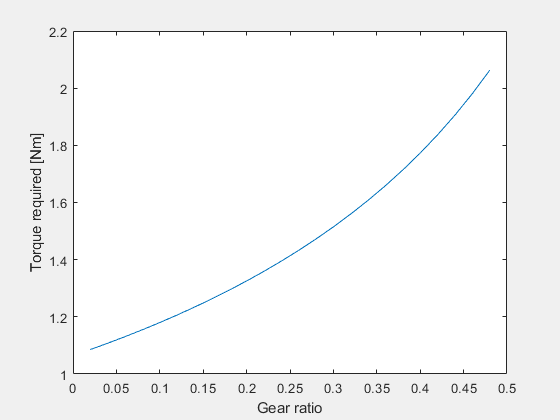

plot((1:24)/50, Tmax(1:24))
ylabel("Torque required [Nm]")
xlabel("Gear ratio")
hold off

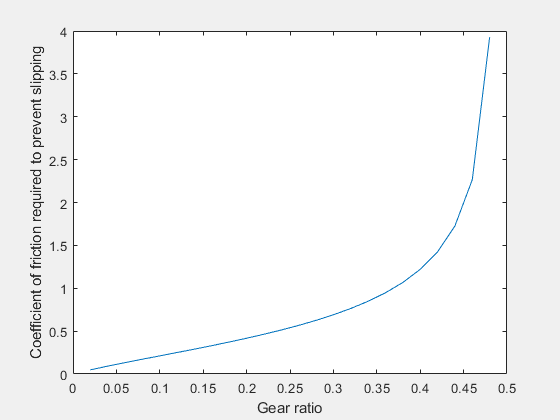


plot((1:24)/50, Cmax(1:24))
ylabel("Coefficient of friction required to prevent slipping")
xlabel("Gear ratio")
hold off


plot((1:24)/50, Fmax(1:24))
ylabel("Force on planet gear tooth")
xlabel("Gear ratio")
hold off

tempsol = mysolver([new_eqns_radius; ...
    separation23 == l3_ab;
    separation35==l5_ab-l3_ab; ...
    l5_ab == 0.041+0.07;
    N_idler == 33; N_sun == 50; ...
    N_planet == 8], 1, sol)

tempsol = struct with fields:
       C_friction7: 0.2
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
     L_body_centre: 0.0437
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
          N_planet: 8.0
             N_sun: 50.0
               a11: 0.0
               a12: 0.0
               a13: 0.0
               a21: 0.0
               a22: 0.0
               a23: 0.0
               a31: 0.0
               a32: 0.0
      

tempsol.r2+tempsol.r5

$$ans = 0.051919354838709677419354838709677$$

Create an animation by using the Runge Kutta method for discrete ODE solution

%Motor torque is not constant, create function to determine motor torque
%based on speed and voltage
motor_stallTorque = 6; % Nm
motor_NLSpeed = 0.6; %rad/s
syms speed stallTorque voltage 
eqns_motor = [
    speed == tv23;
    T_z == 2*motor_stallTorque*(voltage/12.0-speed/motor_NLSpeed)
    stallTorque == motor_stallTorque*(voltage/12.0)]

%Incomplete solution for movement1
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; eqns_motor; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set Motor voltage 
    stallTorque == 6;
    ];

[sol, unsolved] = mysolver(Eqns, 0);

Eqns=[unsolved;
    t13 == 0; t23 ==0 
    tv13 == 0; tv23 == 0;
    ]; 
[sol2, unsolved2] = mysolver(Eqns, 1, sol)


%Start calculations
framesol = []
frameeqs = unsolved
Step_Value = 0.005;
t_beg = 0;
t_end = 10;
t_intial=0;
u_intial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;




for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i); %t13
    up2=u(2,i); %t23
    up3=u(3,i); %tv13
    up4=u(4,i); %tv23
    framesol = [framesol; mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4;], 1)];
    k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], 1);
    k2 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], 1);
    k3 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], 1);
    k4 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
    i
end

f = fieldnames(sol)
nframes = length(framesol)
for i = 1:length(f)
    for j = 1:nframes
        framesol(j).(f{i}) = sol.(f{i});
    end
end

F(length(framesol)) = struct('cdata',[],'colormap',[]);
for j=1:length(framesol)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(framesol(j).s61, framesol(j).s62, framesol(j).rw);
    line([framesol(j).s61,framesol(j).s61+framesol(j).rw*cos(-framesol(j).t63+pi/4)],[framesol(j).s62,framesol(j).s62+framesol(j).rw*sin(-framesol(j).t63+pi/4)])
    
    circle(framesol(j).s51, framesol(j).s52, framesol(j).rw);
    line([framesol(j).s51,framesol(j).s51+framesol(j).rw*cos(-framesol(j).t53+pi/4)],[framesol(j).s52,framesol(j).s52+framesol(j).rw*sin(-framesol(j).t53+pi/4)])
    
    %frame
    line([framesol(j).s51,framesol(j).s61],[framesol(j).s52,framesol(j).s62])
    
    %Tail
    line([framesol(j).s11,framesol(j).s7End1],[framesol(j).s12,framesol(j).s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [framesol(j).step_start1-10; framesol(j).step_start2];
    for i= 1:5
        corner(:,2*i) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i-1)];
        corner(:,2*i+1) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;



movie(fig, F, 1, 1/h);



f=figure('visible','on');
hold on;
%wheels
circle(sol.s61, sol.s62, sol.rw);
line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])

circle(sol.s51, sol.s52, sol.rw);
line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])

%frame
line([sol.s51,sol.s61],[sol.s52,sol.s62])

%Tail
line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])

axis equal;
xlim([-0.6,1])
%ylim([-0.1, 0.5])
%step
corner(:,1) = [sol.step_start1-10; sol.step_start2];
for i= 1:5
    corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
    corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
end
line(corner(1,:), corner(2,:))
% line([sol.step_start1-10, sol.step_start1], [sol.step_start2,sol.step_start2])
% line([sol.step_start1, sol.step_start1], [sol.step_start2, sol.step_start2+ sol.step_height])
% line([sol.step_start1, sol.step_start1+sol.step_width], [sol.step_height, sol.step_height])
hold off;



function f = drawfigure(sol)
    f=figure('visible','on');
    hold on;
    %wheels
    circle(sol.s61, sol.s62, sol.rw);
    line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
    
    circle(sol.s51, sol.s52, sol.rw);
    line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
    
    %frame
    line([sol.s51,sol.s61],[sol.s52,sol.s62])
    
    %Tail
    line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [sol.step_start1-10; sol.step_start2];
    for i= 1:5
        corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
        corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
end

function h = circle(x,y,r)
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit);
end

function solutions = solveParallel(Eqns, var, range)
    [sol, unsolved] = mysolver(Eqns, 0);
    N = length(range);
    solutions=mysolver([unsolved; var == range(1)], 2, sol);
    solutions(N) = solutions(1);
    parfor i = 1:N
        solutions(i) = mysolver([unsolved; var == range(i)], 2, sol);
    end
end